clear all
clc

## PARAMETRI DELLA TELECAMERA

load("C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\" + ...
    "Materiale\PROGETTO CALM\Caratterizzazione CALM\Calibration_steps\pixels_to_world_coordinates\" + ...
    "improvement_test\calibrazione_720_576\dati di calibrazione\calm_camera_calibration.mat");

intrinsics = calm_camera_calibration.Instrinsics_params;
extrinsics = calm_camera_calibration.Extrinsics_params;

load("C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\" + ...
    "Materiale\PROGETTO CALM\Caratterizzazione CALM\Calibration_steps\pixels_to_world_coordinates\" + ...
    "improvement_test\calibrazione_720_576\CameraCalibratorApp\cameraParams.mat");

targetWorldCoordinates = [];

## RICONOSCIMENTO DEL TARGET

% Definizione della variabile stringa
Soggetto = 'Federico'; trialID = "trial2";  targetID = 'quadrato'; debug_on =  true;

% Percorso base
basePath = fullfile('C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\dati test\test_accuratezza_user', Soggetto);

% Estrai l'ultima parola di basePath
[~, baseName] = fileparts(basePath); % baseName sarà 'Enrico'

% Percorso completo del video
videoPath = fullfile(basePath, trialID, targetID, [Soggetto '_' targetID '.mpg']);

% Estrai il percorso senza l'ultimo elemento
[folder_target, ~, ~] = fileparts(videoPath);

% Lettura del video
video = VideoReader(videoPath);

% Creazione della directory per salvare i fotogrammi
outputDir = fullfile(basePath, trialID, targetID); % Usa targetID per creare la directory

% Controlla se la directory esiste, altrimenti creala
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

% Parametri
timeInterval = 1; % Intervallo di tempo in secondi per salvare i fotogrammi
frameRate = video.FrameRate; % Frame rate del video
frameInterval = round(timeInterval * frameRate); % Numero di frame tra due salvataggi

frameCount = 0;
savedFrameCount = 0;

disp('Inizio estrazione dei fotogrammi...');

Inizio estrazione dei fotogrammi...


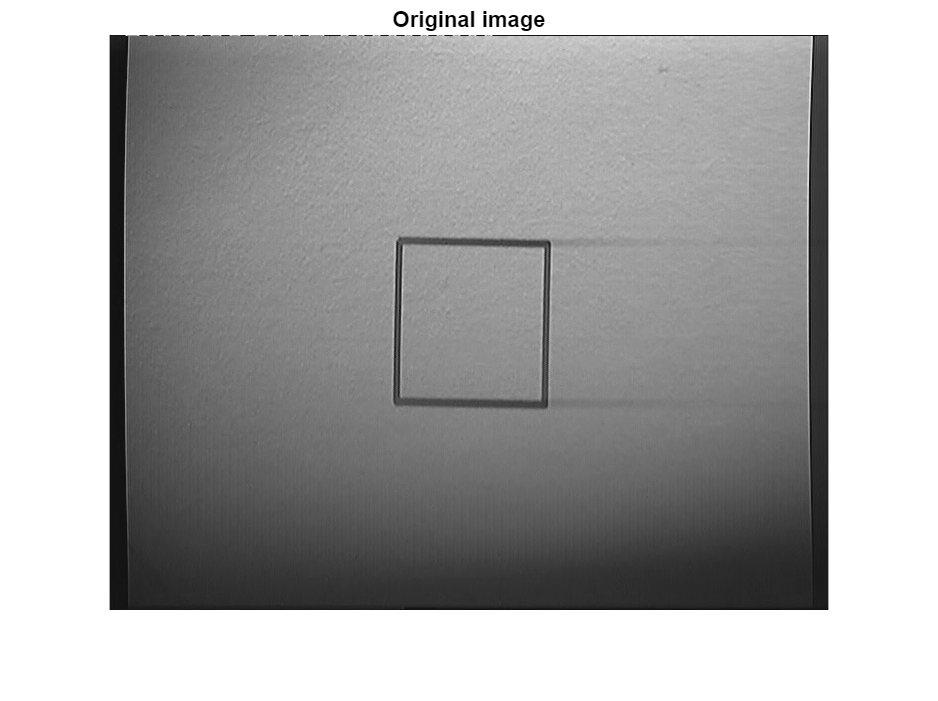

% Ciclo sui frame del video
while hasFrame(video)
    % Leggi il frame corrente
    frame = readFrame(video);
    frameCount = frameCount + 1;
    
    % Salva solo ogni frameInterval-esimo fotogramma
    if mod(frameCount, frameInterval) == 0
        savedFrameCount = savedFrameCount + 1;
        % Nome del file immagine
        frameFile = fullfile(outputDir, sprintf('target_%04d.png', savedFrameCount));
        
        % Salva il fotogramma come immagine PNG
        imwrite(frame, frameFile);
        %fprintf('Salvato: %s\n', frameFile);
    end
end

% Caricare l'immagine
framesDir = outputDir; % Directory in cui i fotogrammi sono stati salvati

% Ottieni la lista di file nella directory
frameFiles = dir(fullfile(framesDir, '*.png')); % Sostituisci '*.png' con il formato corretto (ad esempio, '*.jpg')

% Controlla se ci sono file nella directory
if isempty(frameFiles)
    error('Non ci sono fotogrammi salvati nella directory specificata.');
end

% Ordina i file per nome
[~, idx] = sort({frameFiles.name}); % Ordina i file in ordine alfabetico
sortedFiles = frameFiles(idx);

% Ottieni l'ultimo file
lastFrameFile = fullfile(framesDir, sortedFiles(end).name);

% Leggi l'ultimo fotogramma
image = imread(lastFrameFile);

% Converti l'immagine in scala di grigi (se non lo è già)
if size(image, 3) == 3
    grayImage = rgb2gray(image);
else
    grayImage = image;
end

if debug_on
    figure
    imshow(grayImage)
    title('Original image')
end

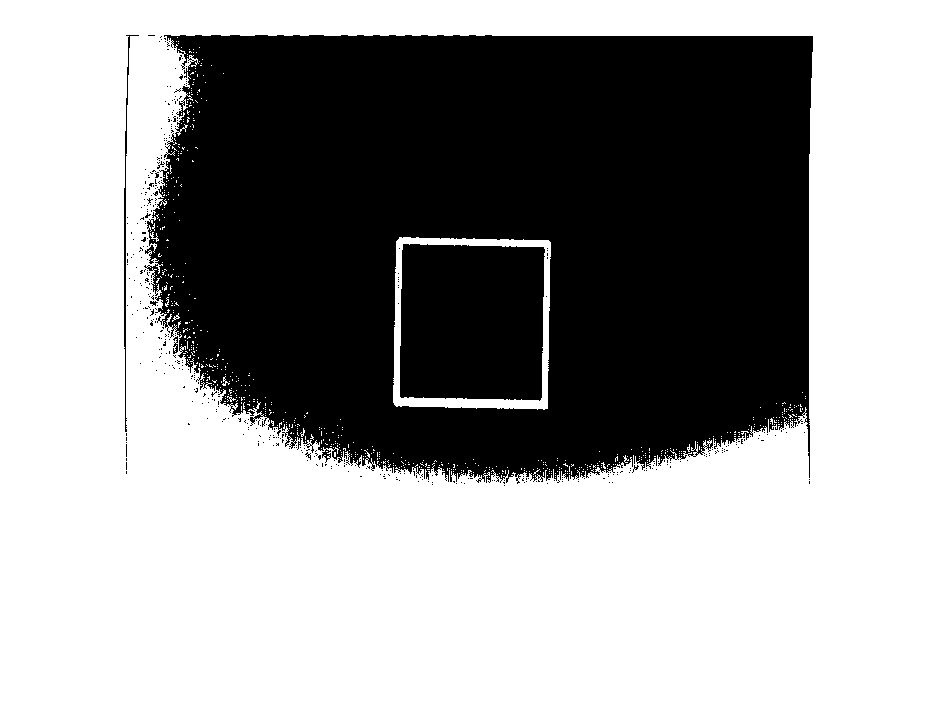

Icomplement = imcomplement(grayImage);
BW = imbinarize(Icomplement,"global");

if debug_on
    figure
    imshow(BW)
end

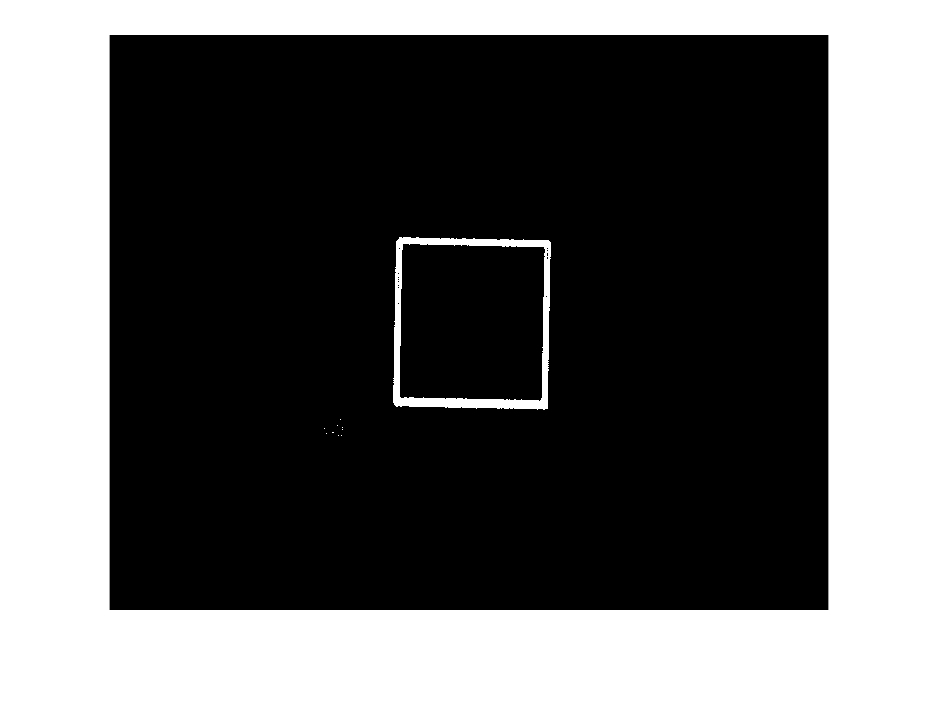

% Definisci una maschera per il quadrato centrale
[rows, cols] = size(grayImage);
centerMask = false(rows, cols);

% Definisci i limiti della regione di interesse (ROI) 
centerRowStart = round(rows * 0.15);
centerRowEnd = round(rows * 0.7);
centerColStart = round(cols * 0.3);
centerColEnd = round(cols * 0.8);
centerMask(centerRowStart:centerRowEnd, centerColStart:centerColEnd) = true;

% Mantieni solo i bordi nella regione centrale
bordersCentral = BW & centerMask;

if debug_on
    figure
    imshow(bordersCentral)
end

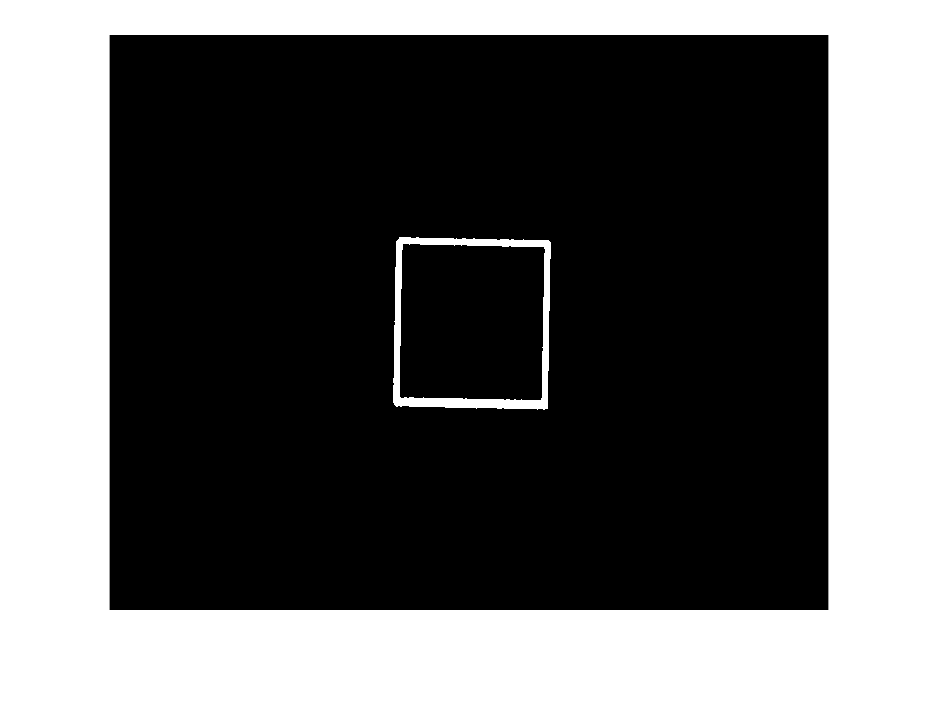

BWclean = bwareaopen(bordersCentral, 50); % Rimuove oggetti con meno di 50 pixel
BWclean = imclose(BWclean, strel('square', 2)); % Chiude piccoli spazi nei bordi

if debug_on
    figure
    imshow(BWclean)
end

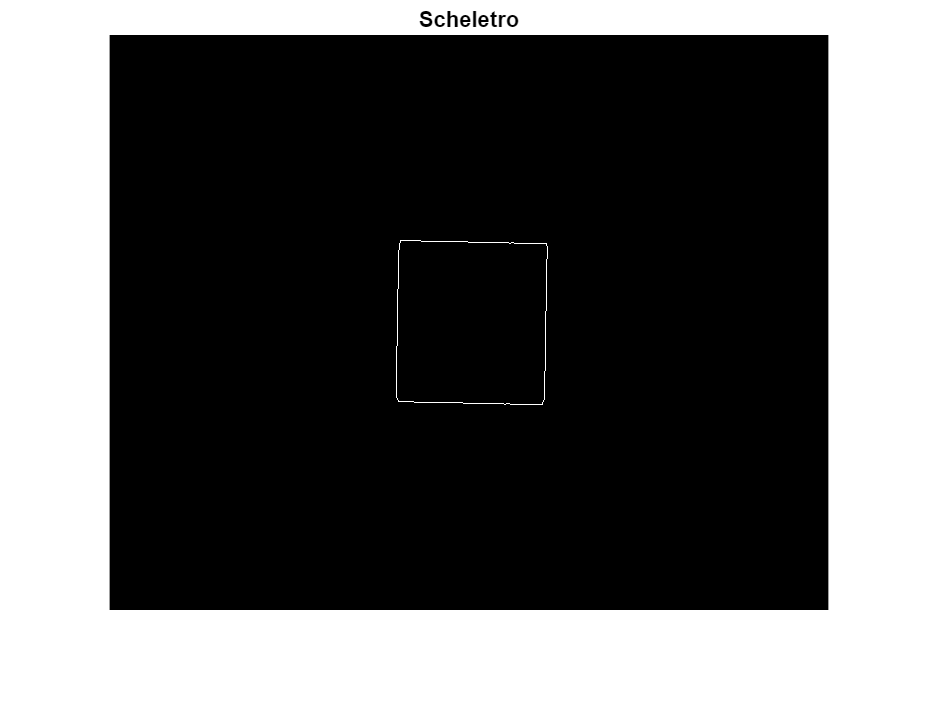

% Ottenere lo scheletro del bordo
skeleton = bwmorph(BWclean, 'skel', Inf);

% Rimuovi ramificazioni corte
skeleton = bwmorph(skeleton, 'spur', 5);

figure
imshow(skeleton);
title('Scheletro');

% Ottenere i pixel dello scheletro
[row, col] = find(skeleton);
SkeletonCoords = [col,row];

### TRAIETTORIE CHIUSE

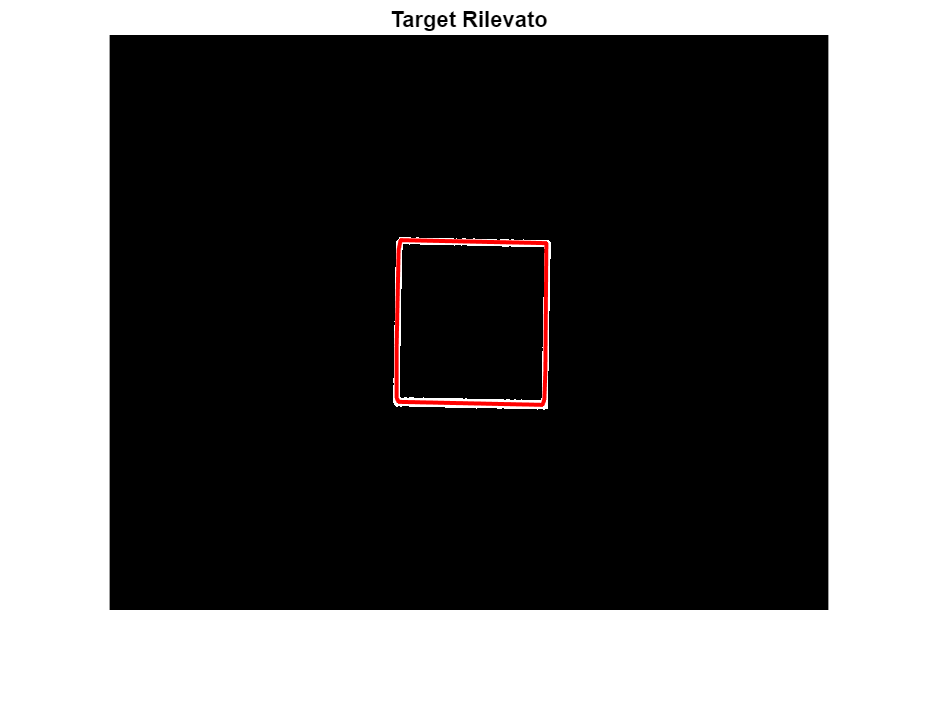

if strcmp(targetID, 'quadrato') || strcmp(targetID, 'cerchio') || strcmp(targetID, 'otto')

    % Trova i contorni ordinati
    [B, ~] = bwboundaries(skeleton, 'noholes');
    % [B, ~] = bwboundaries(BWclean, 'holes');

    boundaryExternal = B{1};

    colExternal = boundaryExternal(:, 2);
    rowExternal = boundaryExternal(:, 1);

    % % Semplifica il contorno esterno usando Douglas-Peucker
    if strcmp(targetID, 'cerchio')
    tolerance = 0.009; % Tolleranza per semplificare i contorni
    end

    if strcmp(targetID, 'quadrato')
    tolerance = 0.005;%0.09; % Tolleranza per semplificare i contorni
    end

    if strcmp(targetID, 'otto')
    tolerance = 0.0009; % Tolleranza per semplificare i contorni
    end

    simplifiedExternal = reducepoly([colExternal, rowExternal], tolerance);

    % Salva le coordinate del contorno esterno
    externalCoords = simplifiedExternal;
    
    % Visualizza i risultati
    figure;
    imshow(BWclean);
    title('Target Rilevato');
    hold on;

    % Plot del contorno esterno
    plot(externalCoords(:, 1), externalCoords(:, 2), 'r-', 'LineWidth', 2);
    hold off;
    
    TargetCoordinatesSmoothed = [externalCoords(:, 1) externalCoords(:, 2)];
    
    % parte nuova
    trajectoryCoords = externalCoords;

    % Passo 1: Sovracampionamento della traiettoria semplificata
    numPoints = 100 * size(trajectoryCoords, 1); % Aumenta il numero di punti (ad esempio 5x)
    tOriginal = 1:size(trajectoryCoords, 1);
    tOversampled = linspace(1, size(trajectoryCoords, 1), numPoints);

    xOversampled = interp1(tOriginal, trajectoryCoords(:,1), tOversampled, 'linear');
    yOversampled = interp1(tOriginal, trajectoryCoords(:,2), tOversampled, 'linear');

    % Passo 2: Interpolazione spline sulla traiettoria sovracampionata
    tSpline = linspace(1, numPoints, numPoints * 2); % Ulteriore interpolazione spline
    xSpline = interp1(1:numPoints, xOversampled, tSpline, 'spline');
    ySpline = interp1(1:numPoints, yOversampled, tSpline, 'spline');

    TargetCoordinatesSmoothed = [xSpline' ySpline'];

    %fine parte nuova    
    
end

### TRAIETTORIE APERTE

if strcmp(targetID, 's')
    % Interpolazione polinomiale (ordine N)
    p_x = polyfit(1:length(col), col, 10);
    p_y = polyfit(1:length(row), row, 10);

    t = linspace(1, length(col),500);

    x_smoothed = polyval(p_x, t);
    y_smoothed = polyval(p_y, t);

    % Visualizzare il risultato
    figure;
    imshow(skeleton);
    title('Scheletro con traiettoria smussata');
    hold on;
    plot(col, row, 'r.', 'MarkerSize', 10); % Punti originali
    plot(x_smoothed, y_smoothed, 'g-', 'LineWidth', 2); % Curva polinomiale
    hold off;
    
    TargetCoordinatesSmoothed = [x_smoothed' y_smoothed'];
end

## PROIETTA IL TARGET NEL MONDO

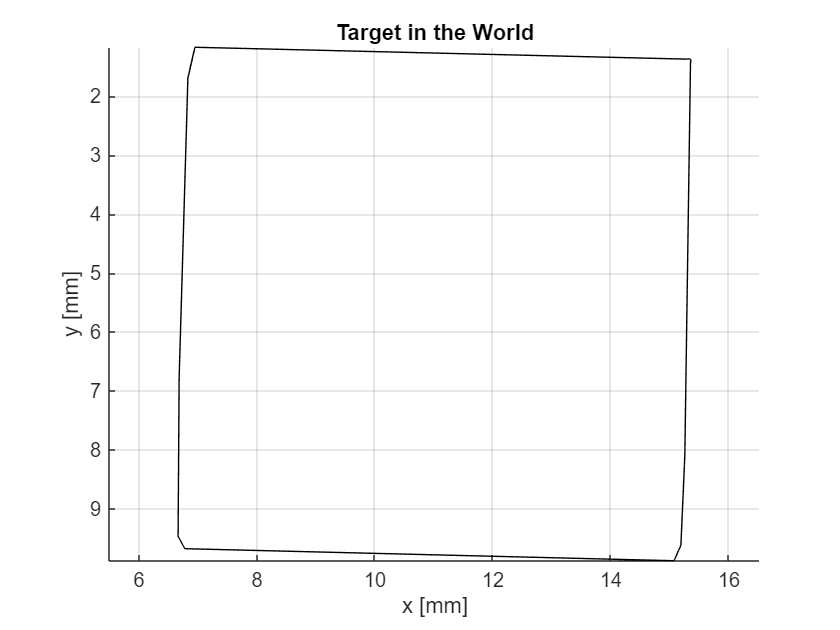

skeletonWorldCoordinates = zeros(length(TargetCoordinatesSmoothed), 2);
 
for i = 1:length(TargetCoordinatesSmoothed)

    skeletonWorldCoordinates(i,:) = img2world2d(TargetCoordinatesSmoothed(i,:), extrinsics, intrinsics); % millimetri

end

% Plot della traiettoria nel mondo
figure
plot(skeletonWorldCoordinates(:,1), skeletonWorldCoordinates(:,2),'k');
hold on
set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo
xlabel 'x [mm]'
ylabel 'y [mm]'
axis equal;
grid on;

title('Target in the World')
box off

if strcmp(targetID, 'quadrato') || strcmp(targetID, 's')
    TargetWorldCoordinates = skeletonWorldCoordinates;
end

## OTTIMIZZAZIONE DEL TARGET NEL MONDO

if strcmp(targetID, 'cerchio')

    x = skeletonWorldCoordinates(:, 1);
    y = skeletonWorldCoordinates(:, 2);

    % Step 2: Costruisci il sistema lineare per trovare il centro
    A = [2*x, 2*y, ones(size(x))];
    b = x.^2 + y.^2;

    % Risolvi il sistema con i minimi quadrati
    params = A \ b;
    xc = params(1); % Centro x
    yc = params(2); % Centro y
    R = sqrt(params(3) + xc^2 + yc^2); % Raggio

    % Step 3: Genera i punti della circonferenza per il plot
    theta = linspace(0, 2*pi, length(skeletonWorldCoordinates(:,2))*5);
    xt = xc + R * cos(theta);
    yt = yc + R * sin(theta);

    % Step 4: Plot dei punti originali e della circonferenza
    figure

    hold on
    plot(x, y, 'b-', 'DisplayName', 'Punti originali'); % Punti originali
    plot(xt, yt, 'r-', 'LineWidth', 2, 'DisplayName', 'Circonferenza Stimata'); % Circonferenza
    plot(xc, yc, 'gx', 'MarkerSize', 5, 'DisplayName', 'Centro Stimato'); % Centro

    legend;
    legend box off

    xlabel('x [mm]');
    ylabel('y [mm]');

    % title(sprintf('Circonferenza Stimata: Centro (%.2f, %.2f), Raggio %.2f', xc, yc, R));
    title(sprintf('Circonferenza Ottimizzata'));
    axis equal;
    grid on;

    % Inverti l'asse y
    set(gca, 'YDir', 'reverse');

    TargetWorldCoordinates = [xt' yt'];
end

if strcmp(targetID, 'otto')

    % Carica le coordinate (skeletonWorldCoordinates deve contenere le coordinate originali)
    x = skeletonWorldCoordinates(:, 1); % Coordinate X
    y = skeletonWorldCoordinates(:, 2); % Coordinate Y

    % Parametri per la riorganizzazione dei vettori delle coordinate (considerando tolerance = 0.0009;)
    N1 = 7907; %48;            % Primo intervallo (da 1 a N1)
    N2_start = 38100; % 192;   % Inizio del secondo intervallo (N2_start a N1+1 in ordine inverso)
    N2_end = 8566;  %49;       % Fine del secondo intervallo
    N3_start = 38423;  %193;   % Inizio del terzo intervallo
    N3_end = length(x);        % Fine del terzo intervallo (fino alla fine del vettore)

    % Creazione del vettore di indici generalizzato
    indici = [1:N1, N2_start:-1:N2_end, N3_start:N3_end];

    % Riorganizzazione dei vettori
    x_reordered = x(indici);
    y_reordered = y(indici);

    % Visualizza la figura originale e quella riorganizzata
    figure;
    plot(x, y, 'k--', 'LineWidth', 1); % Figura originale
    hold on;
    plot(x_reordered, y_reordered, 'r-', 'LineWidth', 2); % Figura riorganizzata

    legend('Originale', 'Riorganizzata');
    legend box off

    xlabel('x [mm]');
    ylabel('y [mm]');

    title(sprintf('8 Ottimizzato'));
    axis equal;
    grid on;

    % Inverti l'asse y
    set(gca, 'YDir', 'reverse');
    box off

    x_otto = x_reordered';
    y_otto = y_reordered';

    TargetWorldCoordinates = [x_otto' y_otto'];

end

## SALVA I DATI DEL TARGET

%Salvo ogni variabile con il rispettivo nome nel folder 
variabili = {'TargetWorldCoordinates'};
for i = 1:numel(variabili)
    varName = variabili{i};
    fileName = fullfile(folder_target, [varName, '.mat']);
    save(fileName, varName);
end

## VERIFICA

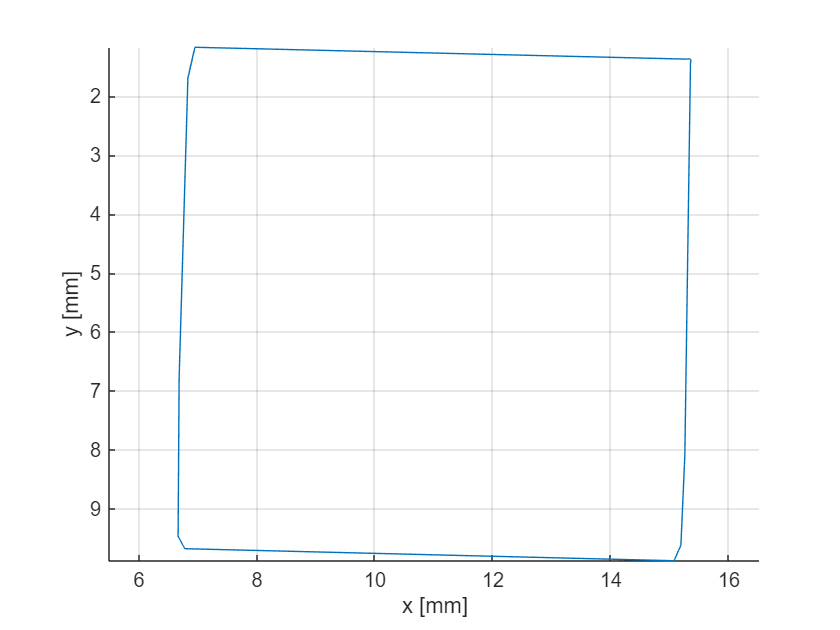

figure
plot(TargetWorldCoordinates(:,1), TargetWorldCoordinates(:,2));
box off
grid on
% Inverti l'asse y
set(gca, 'YDir', 'reverse');
axis equal;
grid on;
xlabel('x [mm]');
ylabel('y [mm]');